% Compute bridge output impedance, Ohms
INVERTER.Zout = computeBridgeOutputImpedance(INVERTER.topology,INVERTER.Vbus,INVERTER.OCP_limit);

## Compute Inverter Snubber Capacitor

This dampens the voltage spike across the IGBTs caused by voltage ringing due to high current switching through the varius parasitic inductances in the system.

Source

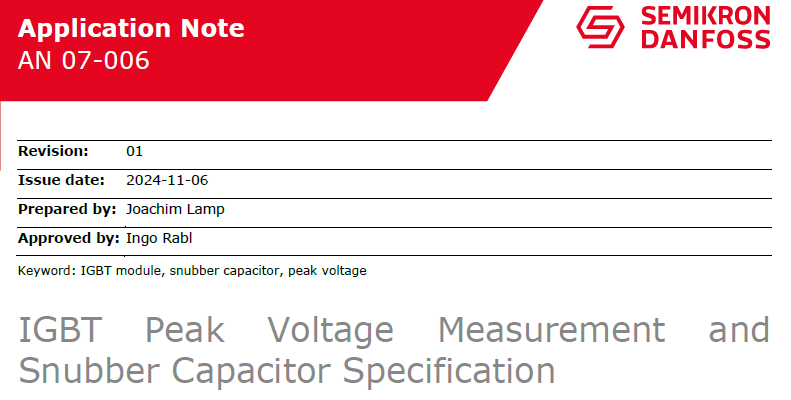

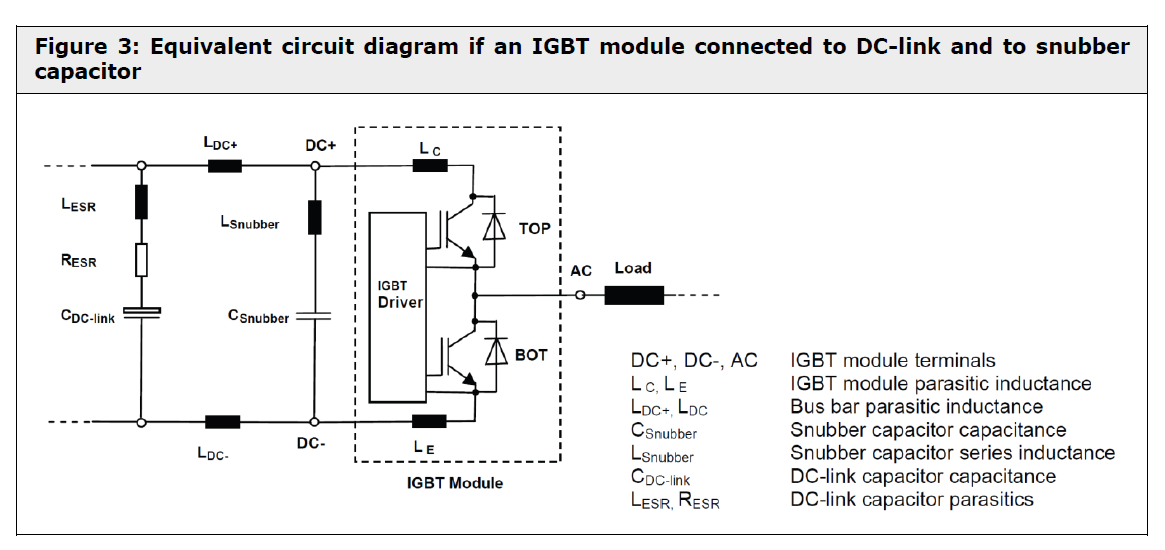

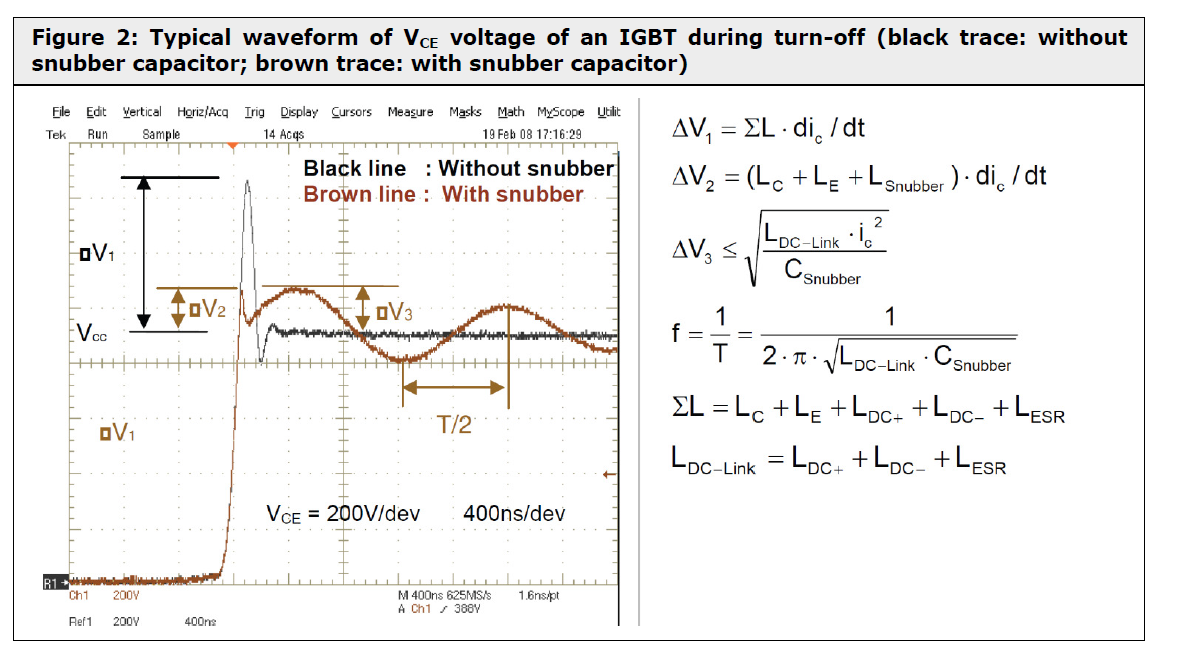

Ldcp = BUSBAR.PosRail_Lpara;       % Positive rail bus bar parasitic inductance, H
Ldcn = BUSBAR.NegRail_Lpara;       % Negative rail bus bar parasitic inductance, H
L_esr = HVBUS.Lesr;                % DC Bus capacitor series parasitic inductance, H

% Total DC link parasitic inductance, H
L_dclink = Ldcp + Ldcn + L_esr;

% Set peak voltage on inverter due to high switching current ringing to 80% of Vce
% max rating of IGBT
INVERTER.Vpeak = IGBT.Vce_max * 0.8;    % V

deltaV3 = INVERTER.Vpeak - INVERTER.Vbus; 

% 20 % overshoot added to max OCD setpoint since the primary current
% will continue to ring-up for a few resonant cycles after an OCD event
i_c_pk = INVERTER.OCP_limit*1.2;

% Compute the minimum capacitance needed to clamp voltage overshoot to INVERTER.Vpeak
INVERTER.Csnub_min = L_dclink*(i_c_pk^2)/(deltaV3^2);

if INVERTER.SnubberCap.C <= INVERTER.Csnub_min
    warning("WARNING: Snubber capacitor not large enough: %0.4f <= %0.4f uF", INVERTER.SnubberCap.C*1e6, INVERTER.Csnub_min*1e6 )
end

% compute peak voltage of ringing with selected snub capacitance
vpk = sqrt((L_dclink*(i_c_pk^2))/INVERTER.SnubberCap.C) + INVERTER.Vbus;


if INVERTER.SnubberCap.C <= INVERTER.Csnub_min
    warning("WARNING: Snubber capacitor not large enough: %0.4f <= %0.4f uF", INVERTER.Csnub*1e6, INVERTER.Csnub_min*1e6 )
end

if INVERTER.SnubberCap.VDC <= vpk
    warning("WARNING: Snubber capacitor voltage rating insufficient: %0.1f <= %0.1f V", INVERTER.SnubberCap.VDC, vpk );
end



## Print Results

fprintf("\n\n################ Inverter Bridge Params BEGIN ##########################\n\n")
fprintf("Bridge output impedance approximation: %0.2f Ohm\n\n", INVERTER.Zout);
fprintf("Bridge minimum snubber capacitance: %0.4f uF\n\n", INVERTER.Csnub_min*1e6);
fprintf("Bridge peak voltage: %0.2f V\n\n", INVERTER.Vpeak);
fprintf("################ Bridge Params END ##########################\n\n")